`pTE function to evaluate the pseudo Transfer Entropy between all variables in data.`

function res = pTE_fun(data, max_lag, opts)
arguments
    data double
    max_lag double
    opts.ss_num = 1000;
    opts.kde_trnsf = "off"
    opts.at_lag = "off"
end

% size of data
[nlen,nvars] = size(data);

% KDE transformation based on kde_trnsf
if opts.kde_trnsf == "on"
    for i = 1:nvars
        data(:,i) = norminv(ksdensity(data(:,i),data(:,i),"Function","cdf"));
    end 
end

% normlaise data based on mean and std dev
data = normalize(data,'center','mean','scale','std');

% lag_vect
if opts.at_lag == "off"
    pTE_all = zeros(nvars,nvars,max_lag);
    pVal = zeros(nvars,nvars,max_lag);
    res.lag_vect = 1:max_lag;
elseif opts.at_lag == "on"
    pTE_all = zeros(nvars);
    pVal = zeros(nvars);
    res.lag_vect = max_lag;
end

for ii = 1:nvars
    svar = data(:,ii);
    k = embed_dim(svar);
    for jj = 1:nvars
        if ii ~= jj
            tvar = data(:,jj);
            l = embed_dim(tvar);
            ss_pTE = zeros(opts.ss_num,1);
            parfor ss = 1:opts.ss_num
                ss_svar = svar(randperm(nlen));
                ss_pTE(ss) = pTE_values(ss_svar,tvar,0,k,l);
            end
            if opts.at_lag == "on"
                pTE_all(ii,jj) = pTE_values(svar,tvar,max_lag,k,l);
                pVal(ii,jj) = sum(ss_pTE >= pTE_all(ii,jj),"all")/opts.ss_num;
            else
                for lag = 1:max_lag
                    pTE_all(ii,jj,lag) = pTE_values(svar,tvar,lag,k,l);
                    pVal(ii,jj,lag) = sum(ss_pTE >= pTE_all(ii,jj,lag),"all")/opts.ss_num;
                end
            end
            
        end
    end
end

res.link_str = pTE_all;
res.true_links = pTE_all .* (pVal <=.05);
res.sig_mat = pVal;

[res.max_str,lag_val] = max(res.true_links,[],3,"omitnan");
res.lag_val = lag_val.*logical(res.max_str);
end

function dim = embed_dim(var)
% For embedding dimension ----------------------------
dim = 0;
end

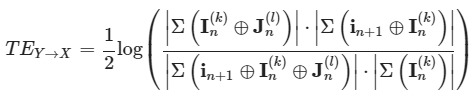

function pTE = pTE_values(svar,tvar,lag,k,l)
% for PTE values given source and target, lag and their embedding dimension
mat1 = [lagmatrix(svar,lag:lag+k) lagmatrix(tvar,1:1+l)];
mat2 = [lagmatrix(tvar,1:1+l) tvar];
mat3 = [lagmatrix(svar,lag:lag+k) lagmatrix(tvar,1:1+l) tvar];
mat4 = [lagmatrix(tvar,1:1+l)];
d1 = det(cov(mat1,"omitrows"));
d2 = det(cov(mat2,"omitrows"));
d3 = det(cov(mat3,"omitrows"));
d4 = det(cov(mat4,"omitrows"));
if (d1*d2)/(d3*d4) >= 0
    pTE = .5*log2((d1*d2)/(d3*d4));
else
    pTE = 0;
end
end